# Challenge 2: Computation of Van der Waals isothermals

by Sophie Cavallini

close all
clear
clc

The scope of this challenge is to calculate and plot the Van der Waals isothermals, using the computation method illustrate in the paper ("Computational derivation of coexistence for van-der-Waals-type equations", 1988 Quintales et al).

Obviously, we need to use the thermal equation:


$$P=\frac{\mathrm{RT}}{v-b}-\frac{a}{T^n v^2 }$$
 

In the case of the Wan der Waals form, n is equal to 0. 

We apply the Maxwell's equal-area rule to subcritical isotherms of the above equation. But, first, we introduce the dimensionless variables:


$$v=\frac{v}{v_c },\;\;\;\;\;\;\;\;\;\overline{T} =\frac{T}{T_c },\;\;\;\;\;\;\;\overline{P} =\frac{P}{P_c }$$


where:


$$v_c =3b,\;\;\;\;\;\;\;\;\;T_c ={\left(\frac{8a}{27\mathrm{Rb}}\right)}^{\frac{1}{n+1}} ,\;\;\;\;\;\;\;P_c =\frac{R}{8b}{\left(\frac{8a}{27\mathrm{Rb}}\right)}^{\frac{1}{n+1}}$$


are, respectively, the molar volume, temperature, and pressure of the the critical point. So, the first equation becomes


$$\overline{\;P} =\frac{8\overline{\;T} }{3\overline{\;v} -1}-\frac{3}{\overline{\;v{\;}^2 } }$$


The intersection of an isotherm $\overline{\;T} =\mathrm{constant}$ and an isobar $\overline{\;P} =\mathrm{constant}$ has 3 points at $\overline{v_1 } ,\overline{\;v_2 } ,\overline{\;v_3 }$ and forms two area 1 and 2, given by


$$\begin{array}{l}
\mathrm{Area1}=\overline{P} \left(\overline{v_2 } -\overline{v_1 } \right)-\int_{\overline{\;v_1 } }^{\overline{v_2 } } {\overline{P} \left(\overline{v} \right)d\overline{v} } =\overline{P} \left(\overline{v_2 } -\overline{v_1 } \right)-\frac{8}{3}\overline{\;T} \mathrm{ln}\left(\frac{3\overline{\;v_2 } -1}{3\overline{\;v_1 } -1}\right)-3\left(\frac{1}{\overline{\;v_2 } }-\frac{1}{\overline{v_1 } }\right),\;\;\;\;\;\;\\
\mathrm{Area2}=\int_{\overline{\;v_2 } }^{\overline{v_3 } } {\overline{P} \left(\overline{v} \right)d\overline{v} } -\overline{P} \left(\overline{v_3 } -\overline{v_2 } \right)=\frac{8}{3}\overline{\;T} \mathrm{ln}\left(\frac{3\overline{\;v_3 } -1}{3\overline{\;v_2 } -1}\right)-3\left(\frac{1}{\overline{\;v_3 } }-\frac{1}{\overline{v_2 } }\right)-\overline{P} \left(\overline{v_3 } -\overline{v_2 } \right)
\end{array}$$


From Maxwell's equal-area rule, the reduced pressure $\overline{\;P_c }$, for which the two phases coexist in equilibrium is the $\bar{\;P}$ that makes the two areas equal. The equation obtaneid is non-linear, so it's difficult to compute its roots.

To avoid calculating this roots directly, we first find the isothermal minimum and maximum points. In this way, we have to compute the roots of cubic (linear) equation, since the derivative is:


$${\left(\frac{\partial \overline{P} }{\partial \overline{v} }\right)}_{\overline{T} } =-\frac{24\overline{T} }{{\left(3\overline{v} -1\right)}^2 }+\frac{6}{{\overline{v} }^3 }$$


then by the iterative method shown in the paper (some kind of bisection method) we compute  $\bar{\;P_c }$.

I fixed the temperature at which to evaluate the isothermal, to change it just modify the value in the script.

The absolute tolerance is set at 10^(-2) and the maximum number of iteration at 900.

%fix isotherm
T = 0.85;
%fix tolerance and maximum number of iteration
tolerance = 1e-2;
maxiter = 900;

Definition of the thermal equation and a function that calculate the integral part of the area.

%Thermal equation of state in the form of Van der Waals, using
%dimensionless variables
P = @(v) 8*T./(3*v-1)-3./v.^2;
%area between pressure P and p(v)
Area = @(va, vb, P, T) 8/3*T*log(((3*vb-1)./(3*va-1)))+3*(1./vb-1./va);

Finding minimum and maximum of P, having fixed T.

%The derivative is:
dP = @(v) -4*T*v.^3+9*v.^2-6*v+1;
coeff_dP = [-4*T 9 -6 1];
stationary_points = sort(roots(coeff_dP));
vM = stationary_points(end);
vm = stationary_points(end-1);
pM = P(vM);
pm = P(vm);

$\overline{P_m }$ can be negative (absurd!) if $\bar{\;T}$ is sufficiently low, in this cases $\bar{P_m }$ must be set to 0.

if pm < 0
    pm = 0;
end

Iterative method:

P0 = 1/2*(pM + pm);
Pj = P0;
for jj = 1:maxiter
    coeff_P = [3*Pj -(Pj+8*T) 9 -3];
    zeros_P = sort(roots(coeff_P));
    v1 = zeros_P(1);
    v2 = zeros_P(2);
    v3 = zeros_P(3);
    Area1 = Pj*(v2 - v1) - Area(v1, v2, Pj, T);
    Area2 = Area(v2, v3, Pj, T) - Pj*(v3-v2);
    if abs(Area1-Area2) < tolerance
        break;
    elseif Area1 < Area2
        P1 = 1/2*(pM + Pj);
        flag = 1;
    else 
        P1 = 1/2*(Pj + pm);
        flag = 0;
    end
    coeff_P = [3*P1 -(P1+8*T) 9 -3];
    zeros_P = sort(roots(coeff_P));
    v1 = zeros_P(1);
    v2 = zeros_P(2);
    v3 = zeros_P(3);
    Area1 = P1*(v2 - v1) - Area(v1, v2, P1, T);
    Area2 = Area(v2, v3, P1, T) - P1*(v3-v2);
    if abs(Area1-Area2) < tolerance
        Pj = P1;
        break;
    elseif (flag)&&(Area1 < Area2)
        Pj = 1/2*(pM + P1);
    elseif ((flag)&&(Area1 > Area2))||(not(flag)&&(Area1 < Area2))
        Pj = 1/2*(Pj+P1);
    else
        Pj = 1/2*(P1+pm);
    end
end
output = [jj, Area1, Area2, v1, v2, v3, Pj];
fprintf('The calculated reduced critical pressure is: %f,', Pj)

The calculated reduced critical pressure is: 0.507791,

fprintf('at the reduced molar volumes: %f, %f, of the coexisting liquid and vapour phases ', v1, v3)

at the reduced molar volumes: 0.553072, 3.092737, of the coexisting liquid and vapour phases 

fprintf('we have performed: %f iterations and the absolute error is: %f', jj, abs(Area1-Area2))

we have performed: 6.000000 iterations and the absolute error is: 0.008436

Plotting the isothermal and some characteristic values.

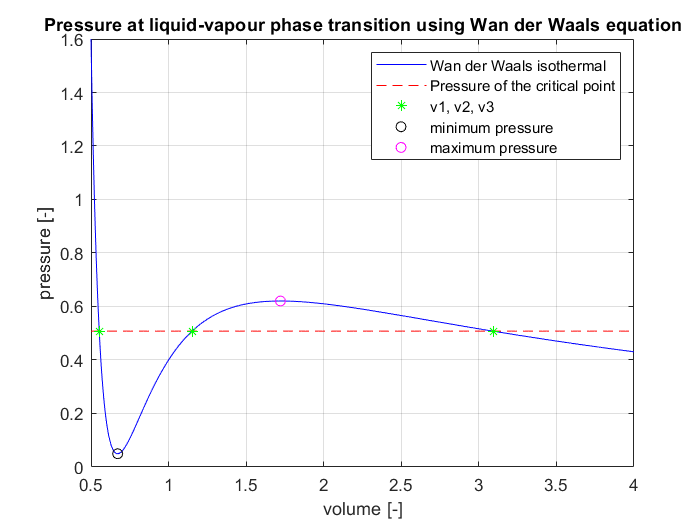

v_int = 0.5:0.001:4;
iso_T = P(v_int);
plot(v_int, iso_T,'b')
hold on
plot(v_int, Pj*ones(size(v_int)),'--r')
plot(zeros_P, Pj*ones(size(zeros_P)),'*g')
plot(vm, pm, 'ok')
plot(vM, pM, 'om')
title('Pressure at liquid-vapour phase transition using Wan der Waals equation')
xlabel('volume [-]')
ylabel('pressure [-]')
legend('Wan der Waals isothermal', 'Pressure of the critical point', 'v1, v2, v3','minimum pressure','maximum pressure')
grid on
hold off